# FMCW雷达信号处理的二维CFAR（2D CFAR、十字CFAR）检测算法

[干货 | FMCW雷达信号处理的二维CFAR（2D CFAR、十字CFAR）检测算法 - 知乎 (zhihu.com)](https://zhuanlan.zhihu.com/p/508870274)

[干货 | 再次解读雷达信号处理中的快速二维CFAR（2D-CFAR、十字CFAR）检测算法 - 知乎 (zhihu.com)](https://zhuanlan.zhihu.com/p/512106070)

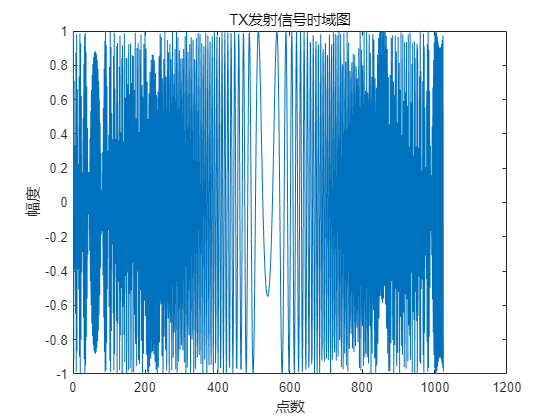

%% 微信公众号：调皮的连续波
%% 知乎：调皮连续波
%% 作者：调皮哥
%% 时间：2022年5月
%% 功能：FMCW雷达发射信号、回波信号、混频、距离维FFT、速度维FFT建模仿真。
%%=========================================================================
clear all;
close all;
clc;
%% 雷达系统参数设置
maxR = 200;           % 雷达最大探测目标的距离
rangeRes = 1;         % 雷达的距离分率
maxV = 70;            % 雷达最大检测目标的速度
fc= 77e9;             % 雷达工作频率 载频
c = 3e8;              % 光速

%% 用户自定义目标参数
r0 = 90; % 目标距离设置 (max = 200m)
v0 = 20; % 目标速度设置 (min =-70m/s, max=70m/s)


%% FMCW波形参数设置
B = c / (2*rangeRes);       % 发射信号带宽 (y-axis)  B = 150MHz
Tchirp = 5.5 * 2 * maxR/c;  % 扫频时间 (x-axis), 5.5= sweep time should be at least 5 o 6 times the round trip time
slope = B / Tchirp;         %调频斜率
endle_time=6.3e-6;          %空闲时间
f_IFmax= (slope*2*maxR)/c ; %最高中频频率
f_IF=(slope*2*r0)/c ;       %当前中频频率

Nd=128;                          %chirp数量 
Nr=1024;                        %ADC采样点数
vres=(c/fc)/(2*Nd*(Tchirp+endle_time));%速度分辨率
% Nr=1024*256;                %和频信号点数设置
Fs=Nr/Tchirp;                 %模拟信号采样频率

t=linspace(0,Nd*Tchirp,Nr*Nd); %发射信号和接收信号的采样时间，在MATLAB中的模拟信号是通过数字信号无限采样生成的。

Tx=zeros(1,length(t)); %发射信号
Rx=zeros(1,length(t)); %接收信号
Mix = zeros(1,length(t)); %差频、差拍、拍频、中频信号

r_t=zeros(1,length(t));
td=zeros(1,length(t));

%% 动目标信号生成

for i=1:length(t)
    
    r_t(i) = r0 + v0*t(i); % 距离更新
    td(i) = 2*r_t(i)/c;    % 延迟时间
    
    Tx(i) = cos(2*pi*(fc*t(i) + (slope*t(i)^2)/2)); % 发射信号 实数信号
    Rx(i) = cos(2*pi*(fc*(t(i)-td(i)) + (slope*(t(i)-td(i))^2)/2)); %接收信号 实数信号
    
    if i<=1024
         freq(i)=fc+slope*i; %发射信号时频图 只取第一个chirp
         freq_echo(i)=fc+slope*i;%回波信号频谱延迟
    end

    Mix(i) = Tx(i).*Rx(i);%差频、差拍、拍频、中频信号
end

%发射信号时域图
figure;
plot(Tx(1:1024));
xlabel('点数');
ylabel('幅度');
title('TX发射信号时域图');

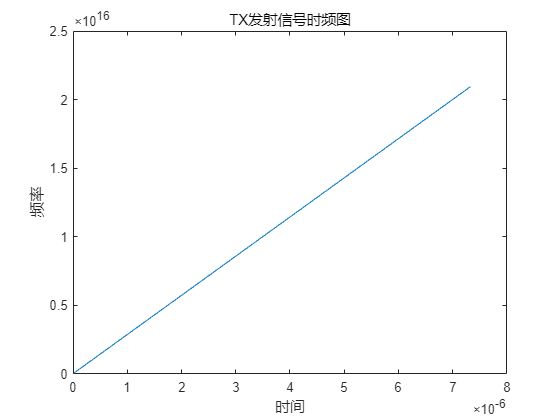


% %发射信号时频图
figure;
plot(t(1:1024),freq);
xlabel('时间');
ylabel('频率');
title('TX发射信号时频图');

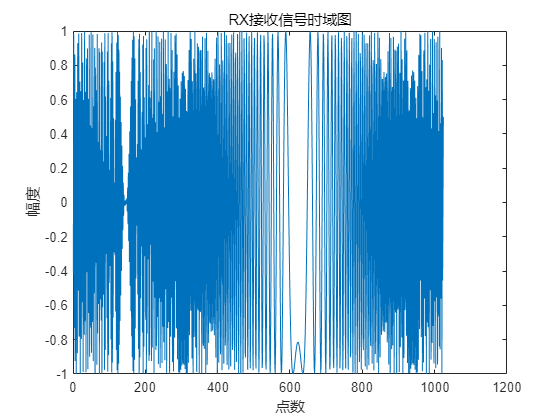


%接收信号时域图
figure;
plot(Rx(1:1024));
xlabel('点数');
ylabel('幅度');
title('RX接收信号时域图');

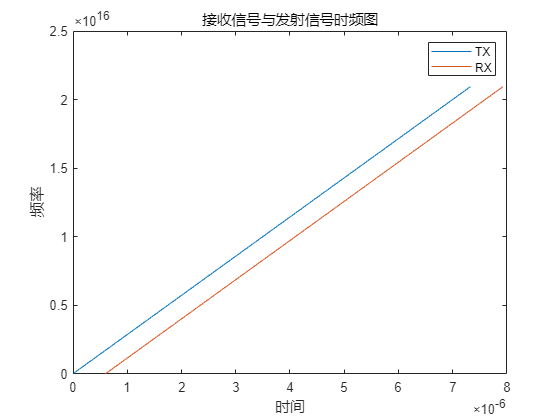


%接收信号与发射信号的时频图
figure;
plot(t(1:1024),freq);
hold on;
plot(td(1:1024)+t(1:1024),freq);
xlabel('时间');
ylabel('频率');
title('接收信号与发射信号时频图');
legend ('TX','RX');

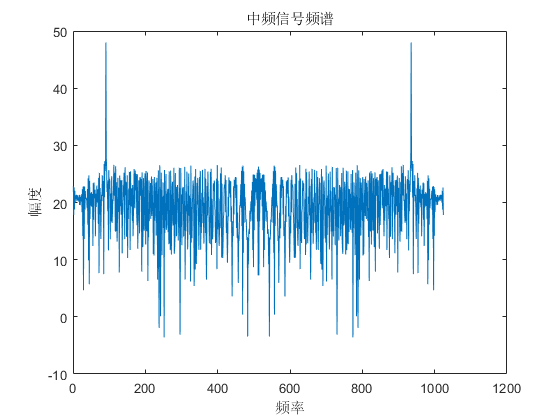


%中频信号频谱 和频信号观察
%figure;
% plot(db(abs(fft(Mix(1:1024*256)))));%查看宽带的和频信号 将chirp的点数改为1024*256即可看到有一个门信号，但注意计算机内存。
% xlabel('频率');
% ylabel('幅度');
% title('中频信号频谱');

figure;
plot(db(abs(fft(Mix(1:1024)))));%查看宽带的和频信号 将chirp的点数改为1024*256即可看到有一个门信号，但注意计算机内存。
xlabel('频率');
ylabel('幅度');
title('中频信号频谱');

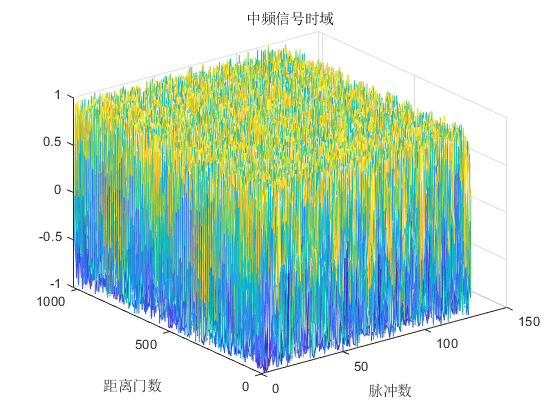


%% 低通滤波 截止频率30MHz  采样频率120MHz
% Mix=lowpass(Mix(1:1024*256),30e6,120e6);
% plot(db(abs(fft(Mix(1:1024*256)))));
% xlabel('频率');
% ylabel('幅度');
% title('中频信号低通滤波器');

%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
signal = reshape(Mix,Nr,Nd);

figure;
mesh(signal);
xlabel('脉冲数')
ylabel('距离门数');
title('中频信号时域');

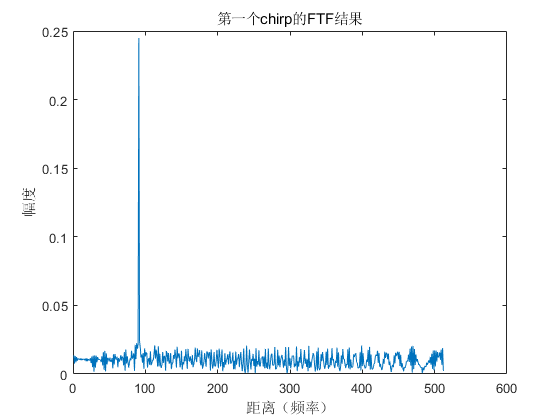


%% 距离维FFT
sig_fft = fft(signal,Nr)./Nr;
sig_fft = abs(sig_fft);
sig_fft = sig_fft(1:(Nr/2),:);

figure;
plot(sig_fft(:,1));
xlabel('距离（频率）');
ylabel('幅度')
title('第一个chirp的FTF结果')

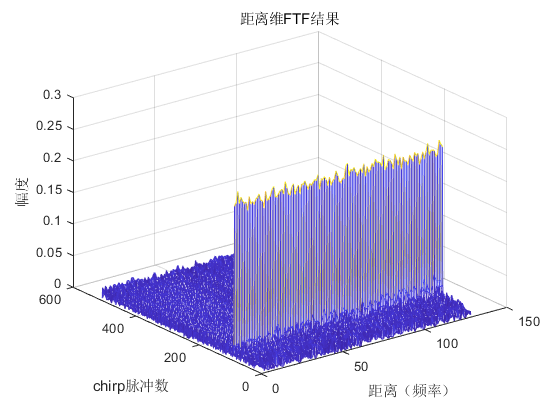



%% 距离FFT结果谱矩阵
figure;
mesh(sig_fft);
xlabel('距离（频率）');
ylabel('chirp脉冲数')
zlabel('幅度')
title('距离维FTF结果')

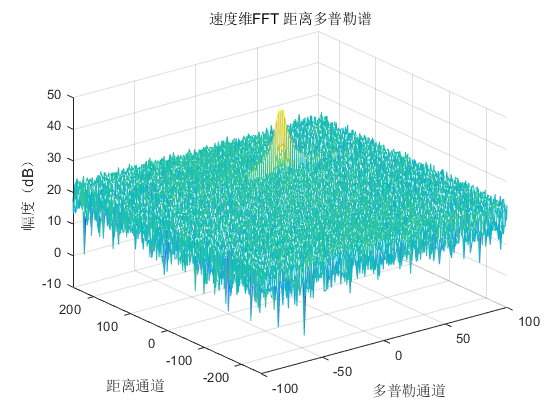


%% 速度维FFT

Mix=reshape(Mix,[Nr,Nd]);
sig_fft2 = fft2(Mix,Nr,Nd);

sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);

figure;
mesh(doppler_axis,range_axis,RDM);
xlabel('多普勒通道'); ylabel('距离通道'); zlabel('幅度（dB）');
title('速度维FFT 距离多普勒谱');

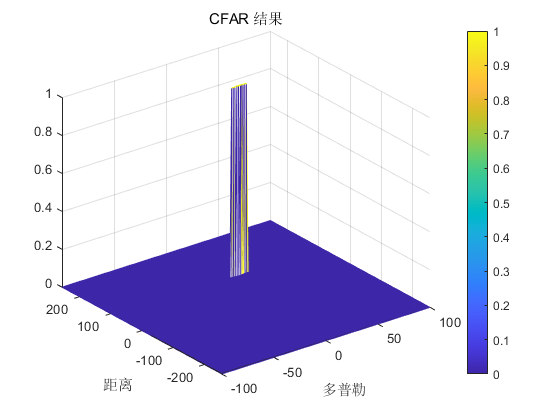



%% CFAR检测算法

%通过完整的距离多普勒图滑动窗口

%在两个维度中选择参考单元的数量
Tr = 8; 
Td = 4;
%选择被测单元（CUT）周围两个维度的保护单元数量，以进行准确CFAR检测
Gr = 4;
Gd = 2;

%以 dB 为单位的 SNR 值偏移阈值
snr_offset = -10*log10(0.25);

%为参考单元上的每次迭代创建一个向量来存储noise_level（噪声电平）
r_margin = 2*(Tr+Gr);
d_margin = 2*(Td+Gd);

r_grid_length = Nr/2-d_margin;
d_grid_length = Nd-r_margin;

noise_level = zeros(r_grid_length,d_grid_length);

%设计一个循环，通过在参考单元和保护单元的边缘提供边距，
%使 CUT 在距离多普勒图上滑动。 对于每次迭代，求所有参考单元中信号电平的和。 
%使用 db2pow 函数将值从对数转换为线性，并平均所有使用的参考单元格的总和值。 
%平均后使用 pow2db 将其转换回对数。 进一步添加偏移量以确定阈值。 
%接下来，将 CUT 下的信号与此阈值进行比较。 如果 CUT  > 阈值，则为其分配值 1，否则置为0。

gridSize = (2*Tr+2*Gr+1)*(2*Td+2*Gd+1);
numGcells = (2*Gr+1)*(2*Gd+1);
numTcells = gridSize - numGcells; %参考单元

% 上述过程将生成一个阈值块，
%该块小于距离多普勒图，因为 CUT 不能位于矩阵的边缘。 
%因此，很少有单元不会被阈值化。 要保持MAP大小相同，请将这些值设置为 0。
sig_CFAR = zeros(size(RDM));

% 此方法计算量大，高于常规的在速度维做一次CFAR 然后在距离维再做一次CFAR。 
%另外，此方法对于距离-多普勒谱矩阵的边界处存在未检测，因此对于处于边界的目标效果不友好，
%可以采用补零法，以及旋绕法检测边界目标
for i = 1:r_grid_length      % 距离边界
    for j = 1:d_grid_length  % 多普勒边界
        % 使用 db2pow 将值从对数转换为线性
%         sig_pow = db2pow(RDM(i:i+d_margin,j:j+r_margin));  %从db变为线性
       sig_pow = db2pow(RDM(i:i+d_margin,j:j+r_margin));     %从db变为线性
       G_pow   = db2pow(RDM(i+Td:i+Td+Gd*2,j+Tr:j+Tr+Gr*2)); %保护单元

        % 所有参考单元内的总和信号
        sig_sum = sum(sum(sig_pow))-sum(sum(G_pow));
        
        % 对所有使用的参考单元格的总和值求平均
        noise_level(i,j) = pow2db(sig_sum/numTcells);
        % 添加偏移量
        sig_threshold = noise_level(i,j) + snr_offset;
        
        % 将 CUT 与阈值进行比较
        if (RDM(i+d_margin/2, j+r_margin/2) > sig_threshold)
            sig_CFAR(i+d_margin/2, j+r_margin/2) = 1;
        end  
    end
end

%display the CFAR output using the Surf function like we did for Range
figure;
mesh(doppler_axis,range_axis,sig_CFAR);
colorbar;
xlabel('多普勒'); ylabel('距离');
title('CFAR 结果');